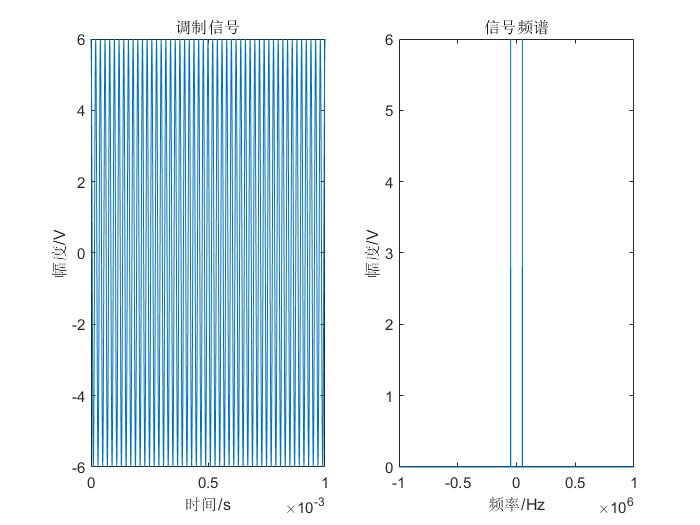

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  FileName:            main.m
%  Description:         模拟调制
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc
clear
close all
Num = 30720; %样点数

N = 20;
A= 6;                   %调制信号幅度
fm=50000;             %调制信号频率
fc=500000;              %载波频率
fs = 30720000 ;           %采样率1/200 * Num * fc
dt = 1/fs;              %时间间隔
t=0:dt:(Num-1)*dt;        %时间向量

Tlabel='时间/s';

freqPixel=fs/Num;       %频率分辨率，即点与点之间频率单位
%%调制信号产生
mf=3;                   %调频指数
y1=A*cos(2*pi*fm*t);    %基带信号
y2=cos(2*pi*fc*t);      %载波信号

%对调制信号进行积分
m_t=A*sin(2*pi*fm*t);   %调制信号

phi_t = mf * 2 * pi * fm / A * cumsum(m_t) / fs;   %相位积分

y=A*cos(2*pi*fc*t+phi_t);%已调信号


%%画图
figure(1)
subplot(1,2,1);
plot(t,y1);title('调制信号');
xlabel(Tlabel);ylabel('幅度/V');
Spectrums(y1,Num,fs);

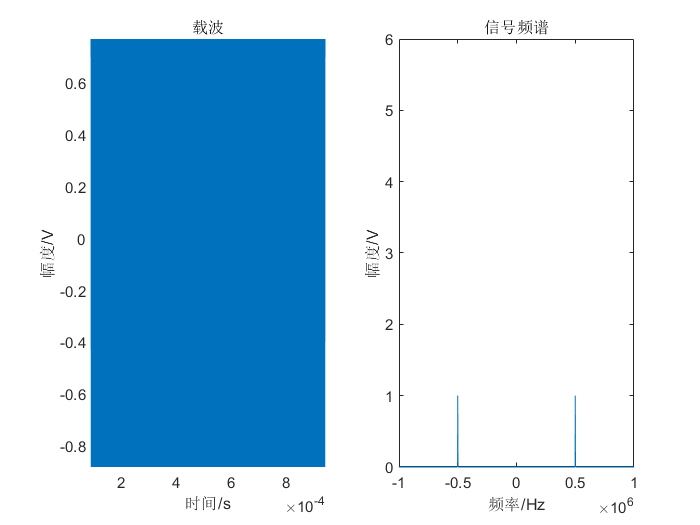


figure(2)
subplot(1,2,1);
plot(t,y2);title('载波');
xlabel(Tlabel);ylabel('幅度/V');
Spectrums(y2,Num,fs);

subplot(1,2,1)
xlim([0.00009 0.00094])
ylim([-0.88 0.77])

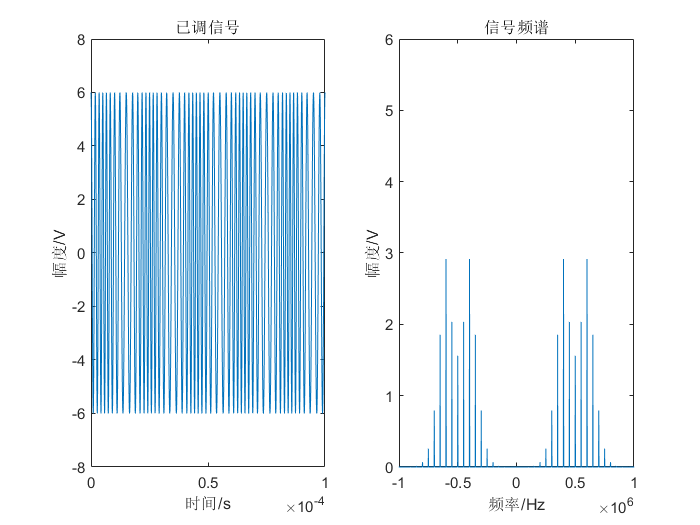

figure(3)
subplot(1,2,1);
plot(t,y);title('已调信号');
xlabel(Tlabel);ylabel('幅度/V');
xlim([0  0.0001])
ylim([-8  8])
Spectrums(y,Num,fs);

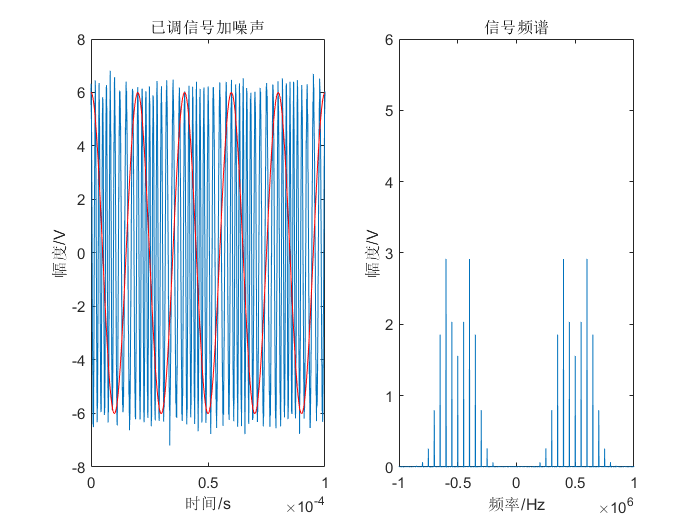

%加噪
y=awgn(y,10);
figure(4)
subplot(1,2,1);
plot(t,y);title('已调信号加噪声');
xlabel(Tlabel);ylabel('幅度/V');
xlim([0  0.0001])
ylim([-8  8])
hold on
plot(t,y1,'r');
Spectrums(y,Num,fs);

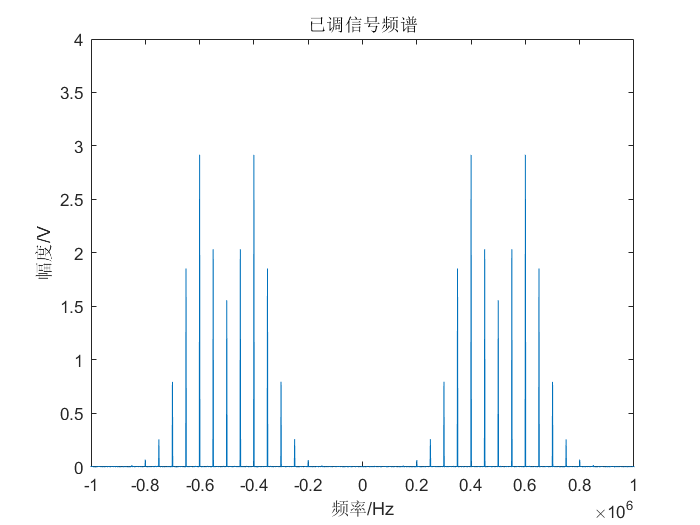


%求信号频谱
L = length(y);
u = fftshift(fft(y,Num)*2/Num);
w=(-Num/2:1:Num/2-1)*fs/Num; %双边  
%w = (0:L-1)'*fs/L - 1/2*fs;
figure(5)
plot(w,abs(u));
title('已调信号频谱');
xlabel('频率/Hz');ylabel('幅度/V');

xlim([-1000000 1000000])
ylim([0.0 4])

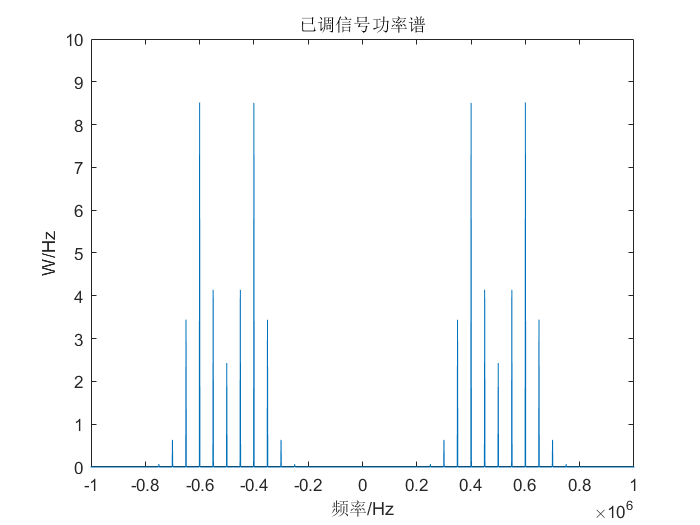

%功率谱
figure(6)
plot(w,abs(u).^2);
title('已调信号功率谱');
xlabel('频率/Hz');
ylabel('W/Hz');
xlim([-1000000 1000000])
ylim([0.0 10])

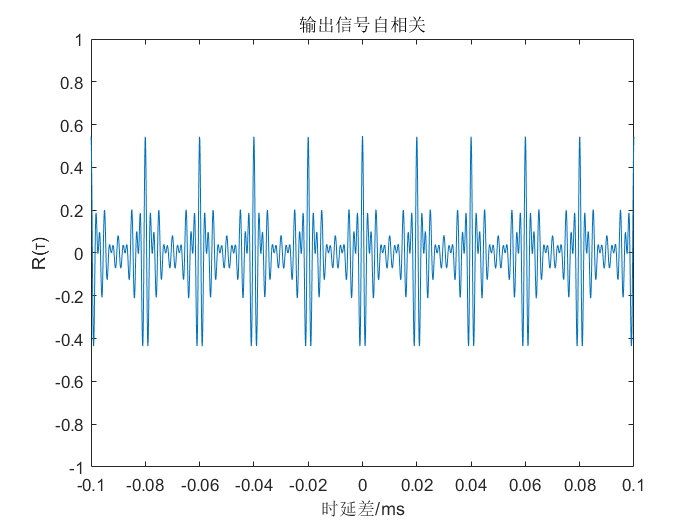


%自相关函数
figure(7)
[Rx,maxlags]=xcorr(y,'unbiased');  %信号的自相关
if fs>10000  %调整时间轴单位及标签,便于观测波形
    plot(maxlags/fs*1000,Rx/max(Rx));
    xlabel('时延差/ms');
else
    plot(maxlags/fs,Rx/max(Rx));
    xlabel('时延差/s');
end
title('输出信号自相关');
ylabel('R(τ)');
ylim([-1,1]);
xlim([-0.10 0.10])


CH1_data = y;
CH2_data = u;
gain_flag = 1;
DivFreq = 30720000/fs - 1;
dataNum = length(CH1_data);
% DA_OUT(CH1_data,CH2_data,DivFreq,dataNum,gain_flag);

aver=mean(y);
v=var(y);



